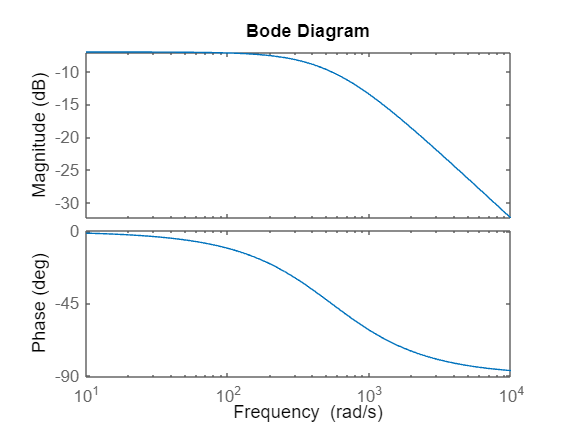

clc; clear;

R = 1.24;			% stator resistance
L = 0.00415;        % stator inductor
J = 0.0003389;      % inertia (Kg-m2)
B = 0.15;           % fraction coefficient, steel on steel (greased)
Kt = 0.853;         % motor torque constant (Nm/Amp)

s = tf('s');
G_curr = 1/(s*L+R); % open-loop transfer function
G_spd = 1/(s*J+B);
G_curr2 = (s*J+B)/((s*L+R)*(s*J+B)+Kt^2);
G_spd2 = Kt/(s*J+B);

G_curr_cl = G_curr/(1+G_curr);  % closed-loop transfer function
G_spd_cl = G_spd/(1+G_spd);